# Source separation using static filtering

In this exercise you will use the [audioTestBench](https://it.mathworks.com/help/audio/ref/audiotestbench-app.html?searchHighlight=audioTestBench&s_tid=srchtitle) to perform real-time interactive audio filtering. In particular, you will separate audio sources by wisely filtering the mixed signal in the frequency domain. If you are interested in advanced source separation, please see this [example](https://it.mathworks.com/help/deeplearning/ug/cocktail-party-source-separation-using-deep-learning-networks.html).

Note: for the following exercise, please turn the speakers on.

Some of the functions used in this livescript require the Signal Processing Toolbox™ or the Matlab Audio Toolbox™. If these support packages are not installed, the functions provide the download links.

% Clear workspace and command window
clear;
clc;

## Non-frequency-overlapped signals

In this section, you will load two audio signals containing voice recordings. The speeches are the spoken words "reform" and "transform", respectively.

Then, you will add a sinusoidal noise at `sine_freq` Hertz to both signals and see the effect on the spectrogram.

voice = load('voice.mat');
t = 0:1/voice.fs:numel(voice.reform)/voice.fs;
t = t(1:numel(voice.reform));

### Visualization and play the original signals

Visualization and play of the "reform" audio signal.

plot_audio(voice.reform, 'reform', true);
audioplayer(voice.reform, voice.fs).playblocking();

Visualization and play of the "transform" audio signal.

plot_audio(voice.transform, 'transform', true);
audioplayer(voice.transform, voice.fs).playblocking();

### Define a sinusoidal noise signal

Change the `sine_freq` and get familiar with sinusoidal audio noise.

sine_freq = 2000;
sine = .01 * sin(2*pi*sine_freq * t).';

### Add noise to the original signals

voice.reform_sine = voice.reform + sine;
voice.transform_sine = voice.transform + sine;

### Visualize and play the "reform" noisy signal

plot_audio(voice.reform_sine, 'reform+sine', true);
audioplayer(voice.reform_sine, voice.fs).playblocking();

### Visualize and play the "transform" noisy signal

plot_audio(voice.transform_sine, 'transform+sine', true);
audioplayer(voice.transform_sine, voice.fs).playblocking();

### Save the noisy audio to a wave file (.wav)

Save the noisy signals to a wave (.WAV) file for the following processing.

audiowrite("reform_sine.wav", voice.reform_sine, voice.fs);
audiowrite("transform_sine.wav", voice.transform_sine, voice.fs);

## Simple interactive source separation

In this section, you will implement a simple source separation using the [audioTestBench](https://it.mathworks.com/help/audio/ref/audiotestbench-app.html?searchHighlight=audioTestBench&s_tid=srchtitle) app on the previously saved noisy signals.

Press the RUN button to open the App.

### Band-pass filter to isolate the sine

To filter out the voice and only take the sinusoidal component, you will implement a band-pass notch filter.

Firstly, load one of the previously saved audio files using the Input section of the TEST BENCH VIEW panel.

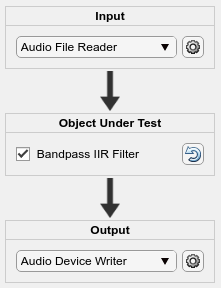

Click on the wheel to open the Audio File Reader window.

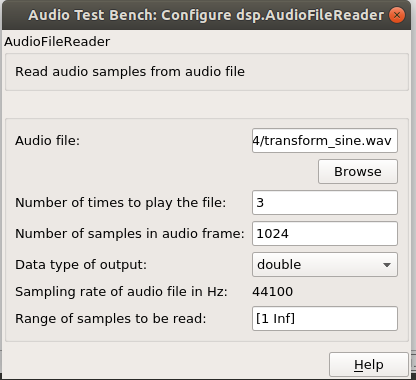

Click the Browse button to select the WAV file to use. Set the other parameters as in the figure above, then close the window.

Then open the desired visualization panels by clicking the respective buttons in the Visualization section.

Thus, move:

- The `Center Frequency` knob (leftmost) to the sine frequency. This will tune the center frequency of the bandpass filter harmonic response.

- The `Q` knob (rightmost) to 70. This will reduce the filter bandwidth in order to filter out the voice signal and only select the sine component.

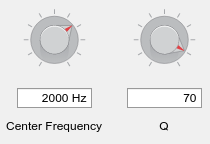

Then press the RUN button to run the app. You should hear the sine only. The visualization tools should show a result similar to the one depicted below.

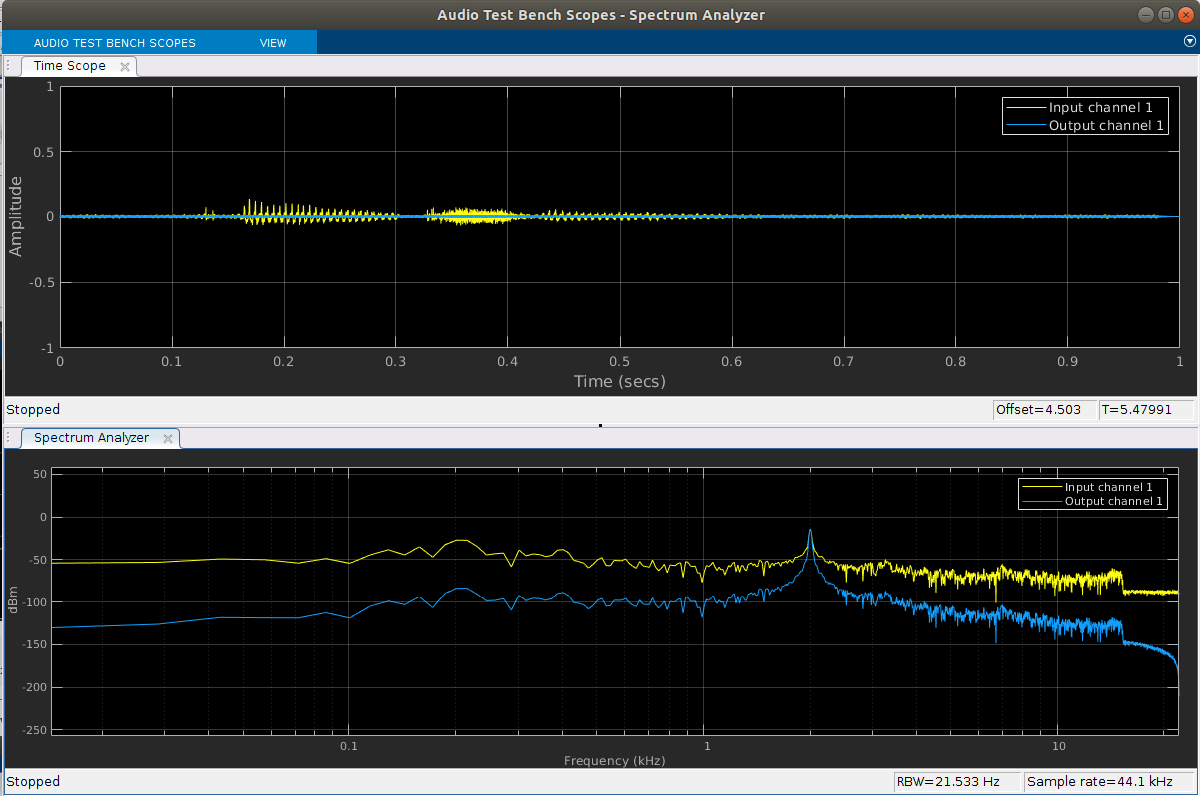

audioTestBench('-close'); % close previous window
audioTestBench(audiopluginexample.BandpassIIRFilter); % open a new window

Exercise: change the frequency and quality factor during the execution and get familiar with the plugin parameters.

### Band-stop filter to isolate the voice

To filter out the sine and only take the voice, you will implement a band-stop notch filter. This does the opposite of the previous section but using a different plugin.

Press the RUN button to open the App.

Firstly, load one of the previously saved audio files using the Input section of the TEST BENCH VIEW panel.

Click on the wheel to open the Audio File Reader window.

Click the Browse button to select the WAV file to use. Set the other parameters as in the figure above, then close the window.

Then open the desired visualization panels by clicking the respective buttons in the Visualization section.

Thus, move just one of the notch frequency slides to the sine frequency. Note that by default, frequency number 7 is already set to 2000 Hertz, which is the original value of `sine_freq`.

Finally, run the app to see the result. You should hear the voice only. The visualization tools should show a result similar to the one depicted below.

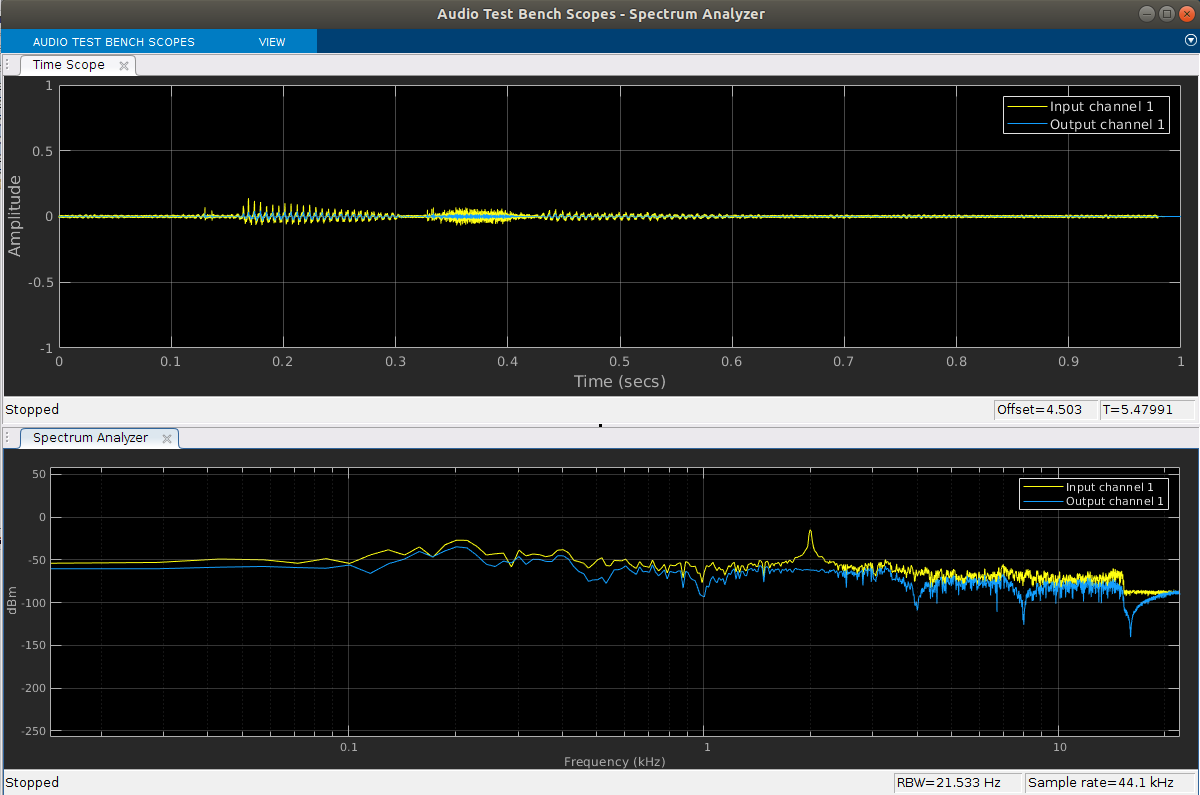

audioTestBench('-close'); % close precious window
audioTestBench(audiopluginexample.MultiNotchFilter); % open a new window

Exercise: change the frequency and quality factor during the execution and get familiar with the pugin parameters.

## Frequency-overlapped signals

When signals overlap both in the time and frequency domains, a simple frequency filter may not be enough to separate sources. In this example, the loaded voice will be mixed with your recorded voice.

### Load the first voice

voice = load('voice.mat'); % loaded voice

### Record the second voice

Press the 'Start recording' button and record your voice.

 

% Voice recording
recorder = audiorecorder(voice.fs,24,1); % audiorecorder object
record_time = length(voice.transform)/voice.fs

record_time = 1.8141


% record
w = waitbar(0, '** Recording started! Say something ***'); % warn the user

tic;
recorder.record(record_time); % recording
while toc < record_time
    waitbar(toc/record_time, w);
end
close(w);
recorder.play(); % play the recorded audio
recorded_voice = recorder.getaudiodata; % get the recorded audio

### Mix the signals

Normalize and sum the two voices. Normalization is carried out by subtracting the signal average value and dividing it by its maximum absolute value. By doing this, we can mix the two signals avoiding that the strongest one covers the weakest one.

if length(recorded_voice) > length(voice.transform)
    % cut the recorded voice
    recorded_voice = recorded_voice(1:length(voice.transform));
elseif length(recorded_voice) < length(voice.transform)
    % pad the recorded voice
    recorded_voice = [recorded_voice, zeros(1, length(voice.transform) - length(recorded_voice) )];
end

% normalize the two signals
voice.transform = voice.transform - mean(voice.transform);   % mean subtraction
voice.transform = voice.transform/max(abs(voice.transform)); % divide by the maximum absolute value

recorded_voice = recorded_voice - mean(recorded_voice);   % mean subtraction
recorded_voice = recorded_voice/max(abs(recorded_voice)); % divide by the maximum absolute value

% sum the two signals
two_voices = .5 * voice.transform + .5 * recorded_voice;

#### Visualize and play the loaded voice

plot_audio(voice.transform, 'Transform', true); % visualization
audioplayer(voice.transform, voice.fs).playblocking(); % play and wait

#### Visualize and play the recorded voice

plot_audio(recorder.getaudiodata, 'Recorded', true); % visualization
audioplayer(recorder.getaudiodata, voice.fs).playblocking(); % play and wait

#### Visualize and play the mixed signal

plot_audio(two_voices, 'Both', true); % visualization
audioplayer(two_voices, voice.fs).playblocking(); % play and wait

### Try to separate the two sources

Write the mixed signal to a  file and run the audioTestBench. Follow the previous instructions (see the section **Band-pass filter to isolate the sine**) to load and process the mixed signal file. Try to separate the two sources by tuning the band-pass filter parameters.

audiowrite("transform_recorded.wav", two_voices, voice.fs); % write the mixed audio file
audioTestBench('-close'); % close previous window
audioTestBench(audiopluginexample.BandpassIIRFilter); % open a new window

## Further readings

Separate sources that overlap in both the time and the frequency domain is challenging. For an advanced application like this, please read this [example](https://it.mathworks.com/help/deeplearning/ug/cocktail-party-source-separation-using-deep-learning-networks.html).

## Helper functions

### Plot audio

This function normalize the signal and shows it in the time and frequency domains, separately. Eventually, the spectrogram is also computed using the [spectrogram](https://it.mathworks.com/help/signal/ref/spectrogram.html) function and depicted.

Inputs:

- `x`: the audio signal array

- `label`: the label of the signal x to print in the title

- `bool_or_features`: a bool to compute the spectrogram or the pre-computed spectrogram features of the signal x (optional)

function plot_audio(x, label, bool_or_features)

% Normalize the signal
x = normalize_audio(x);

% Plot the signal
figure();

if nargin > 2 % if the features input parameter is passed
    num_subplots = 3; % create 3 subplots
else
    num_subplots = 2; % create 2 subplots
end

% First subplot: signal in the time domain
subplot(num_subplots,1,1);
plot(x);
axis tight; % tight visualization
ylim([-1, 1]); % the signal is normalized, thus set the y axis limits to [-1, 1]
xlabel('sample');
ylabel('amplitude');
if nargin > 1 && not(isempty(label)) % if the label input parameter is passed, put it in the title
    title(strcat('Signal: "', string(label), '"'));
end

% Second subplot: signal in the frequency domain
subplot(num_subplots,1,2);
X = fftshift(fft(x));
omega = -1/2:1/numel(x):1/2-1/numel(x);
plot(omega, abs(X));
xlabel('normalized frequency');
ylabel('spectrum amplitude');

if nargin > 2 && ~isempty(bool_or_features) ...
    && ~isequal(bool_or_features, false) % if the bool_or_features input parameter is passed
    if isequal(bool_or_features, true)
        features = abs(spectrogram(x, round(length(x)/100), 0, 256))';
        feature_name = 'Spectrogram';
    else
        features = bool_or_features;
        feature_name = 'Feature';
    end
    % Third subplot: spectrogram (i.e. signal in the time-frequency domain)
    subplot(num_subplots,1,3);
    pcolor(log(features' + 1)); % depict the spectrogram log intensity in pseudo-color
    caxis(prctile(features(:), [0, 97.5])); % threshold at 97.5 percentile
    shading flat; % set the color shading to flat
    xlabel('time slots');
    ylabel('frequency bands');
    title([feature_name, ' log amplitude']);
end
end


### Normalize audio

This function normalizes the signal by subtracting its mean and dividing by its maximum absolute value.

Inputs:

- `x`: the audio signal array

Returns:

- `y`: the normalized audio signal array

function y = normalize_audio(x)
% Normalize the signal for visualization and processing purposes
y = x - mean(x);   % mean subtraction
y = y/max(abs(y)); % divide by the maximum absolute value
end
